% SET OPTIONS
importSimLogs = false;
importRealData = true;
importMocap = true;
importImages = true;
rtRounding = 10;

%File directories
%imgFolder = fullfile('.', '/QuadSimEnv/Results/Traj-0024');
parentFolder = '\Tests\RobMech\Dynamic\TestSeries_3\static_low2';
imgFolder = fullfile('.', parentFolder);
%logFile = fullfile('.','/QuadSimEnv/Results/Traj-0024/simout_ideal_100hz_16s.mat');
imuLogFolder = fullfile('.', parentFolder, '\imuReadings.mat');
mocapLogFolder =fullfile('.', parentFolder, '\mocapLog.mat');


% INITIALISE CONSTANTS

global g;
g = [0; 0; -9.7952];

%INITIALISE WORLD MAP
map = load('./Resources/map.mat');

%Camera variables
%K = [1274.58238813250 0 627.693937913345; 0 1273.36371905619 405.441250468717; 0 0 1]; %23 mm calibration
%K=   [302.9345 0 161.3325; 0 310.8146 131.1024; 0 0 1.0000]; %31 mm calib, esp32 
K = [458.944297528687 0 249.584321044399; 0 459.543641247509 172.625660963493; 0 0 1];%esp32 svga
%K = [1107 0 960; 0 1107 540; 0 0 1]; %virtual camera

%Checkerboard variables
X_pnts_W = map.worldObjectStruct.checkers.Corners/1000; %in m
checkerSize = map.worldObjectStruct.checkers.NumSquares;
checkerEdgeLength = map.worldObjectStruct.checkers.SquareSize; %mm
checker_w_mm = 31*checkerSize(2);
checker_h_mm = 31*checkerSize(1);

%Known coordinate transformations (mapping)
Rt_uw2rw  = map.worldObjectStruct.transforms.rt_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;
Rt_rc2rq = map.worldObjectStruct.transforms.rt_gencam2genquad;


%other variables
p3pResult = struct();
inlierThreshold =1;


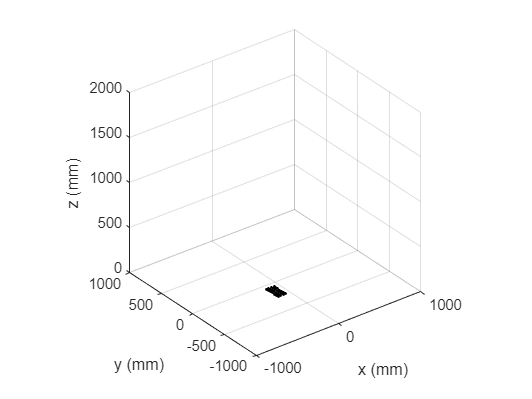

%INTIALISE PLOT
close all

%ADD TRAJECTORIES
plotStruct = initPlots('KneipN', 'Verification', 'EKF');
p3pPlotting.addCheckerboard(plotStruct.traj.Ax, X_pnts_W);

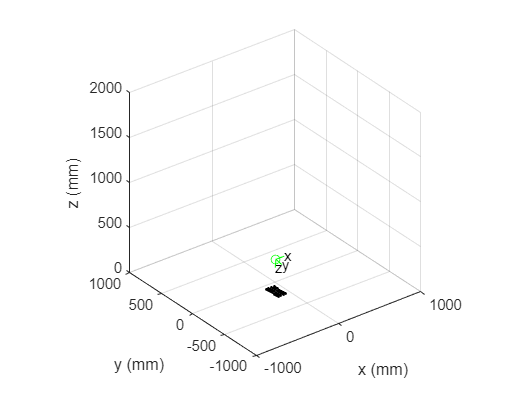

%IMPORT & PLOT LOGGED DATA

if (importSimLogs == true) || (importMocap == true) || (importRealData == true)

    %Create struct to hold verification data
    groundTruth.quadState = [];
    groundTruth.quadRt = createArray(3,4, 0, 'double');
    groundTruth.quadTime = createArray(1, 0, 'datetime');
    groundTruth.quadTime = datetime(groundTruth.quadTime, 'Format', 'yyyyMMdd_HHmmss_SSS');
    groundTruth.camPose = createArray(7,0, 'double');
    groundTruth.camTime = createArray(1, 0, 'datetime');
    groundTruth.camTime = datetime(groundTruth.camTime, 'Format', 'yyyyMMdd_HHmmss_SSS');
    groundTruth.elapsedTime_synced = createArray(1,0, 'double');

    imu.rawdata = createArray(6,0, 'double');
    
    imu.time = createArray(1, 0, 'datetime');
    imu.time = datetime(imu.time, 'Format', 'yyyyMMdd_HHmmss_SSS');

    %Import sim data
    if importSimLogs ==true
        [groundTruth.quadRt, groundTruth.quadTime, groundTruth.quadState, groundTruth.camTime, imu.rawdata, imu.time] = imgFuncs.importSimLog(logFile);
    end
    
    %Or import mocap data
    if importMocap == true
        Rt_mc2rw = map.worldObjectStruct.transforms.rt_mocap2world;
        Rt_mcq2rq = map.worldObjectStruct.transforms.rt_mcquad2genquad;
        [groundTruth.quadRt, groundTruth.quadState, groundTruth.quadTime] = importMocapLog(mocapLogFolder,  Rt_mc2rw, Rt_mcq2rq);
    end

    %Or import real imu logs
    if importRealData ==    true
        imuLog = load(imuLogFolder);
        imu.time = datetime(imuLog.timestamps_imu', 'InputFormat', 'yyyyMMdd_HHmmss_SSS'); 
        imu.rawdata = imuLog.imuMsgLog';  
        imu.calibdata = createArray(6,size(imu.time, 2), 'double');
        %Also calibration?
        %Set calibration parameters
        ba_calib = [-0.173; -0.164; 0.329];
        Ka_calib = [0.992 0 0; 0 0.989 0; 0 0 0.975];
        %bg_calib = [0.009; -0.038; -0.006];
        bg_calib = [0 0 0]';
        Kg_calib = [1 0 0; 0 1 0; 0 0 1];
        R_imu2rq = eul2rotm(deg2rad([-0.431, -1.874, 0]), 'XYZ');
        Rt_imu2rq(1:3, 1:3) = R_imu2rq;   
        for r=1:size(imu.time, 2)
            imu.calibdata(:,r) = [(Kg_calib * imu.rawdata(1:3, r) - bg_calib); (Ka_calib * imu.rawdata(4:6, r)-ba_calib)];
        end
        
    end

    %%synchronise ground truth and imu data
    startTime_imu = imu.time(1);
    endTime_imu = milliseconds(imu.time(end)-startTime_imu)/1000;
    for t=1:size(groundTruth.quadTime,2)
        groundTruth.elapsedTime_synced(1,t)=milliseconds(groundTruth.quadTime(1,t)-startTime_imu)/1000;
    end
    %get closest times
    [closestDiff, closestIndex] = min(abs(groundTruth.elapsedTime_synced));
    syncedTime_zeroIndex_gt = closestIndex;
    [closestDiff, closestIndex] = min(abs(groundTruth.elapsedTime_synced(1,:)-endTime_imu));
    syncedTime_endIndex_gt = closestIndex;

        
    %update plots
    lineObj_Ver = plotStruct.traj.plotLines.Verification.line;
    axTextArr_Ver=plotStruct.traj.plotLines.Verification.frameText;
    axLineArr_Ver = plotStruct.traj.plotLines.Verification.frameLines;
    p3pPlotting.updateTraj(lineObj_Ver, axTextArr_Ver, axLineArr_Ver, groundTruth.quadRt);

end

%Import images for P3P    
if importImages == true  
    
    imageStream = struct();
    imageStream.img = [];
    imageStream.time = createArray(1, 0, 'datetime');
    imageStream.time = datetime(imageStream.time, 'Format', 'yyyyMMdd_HHmmss_SSS');
    
    if importRealData == true
        [imageStream.img, imageStream.time] = imgFuncs.importImageSeq(imgFolder, 1);
    else
        [imageStream.img, imageStream.time] = imgFuncs.importImageSeq(imgFolder, 0);
    end
    imageStream.res = size(imageStream.img(:,:,1));
end

Working on frame 1
Working on frame 2
Working on frame 3
Working on frame 4
Working on frame 5
Working on frame 6
Working on frame 7
Working on frame 8
Working on frame 9
Working on frame 10
Working on frame 11
Working on frame 12
Working on frame 13
Working on frame 14
Working on frame 15
Working on frame 16
Working on frame 17
Working on frame 18
Working on frame 19
Working on frame 20
Working on frame 21
Working on frame 22
Working on frame 23
Working on frame 24
Working on frame 25
Working on frame 26
Working on frame 27
Working on frame 28
Working on frame 29
Working on frame 30
Working on frame 31
Working on frame 32
Working on frame 33
Working on frame 34
Working on frame 35
Working on frame 36
Working on frame 37
Working on frame 38
Working on frame 39
Working on frame 40
Working on frame 41
Working on frame 42
Working on frame 43
Working on frame 44
Working on frame 45
Working on frame 46
Working on frame 47
Working on frame 48
Working on frame 49
Working on frame 50
Working o

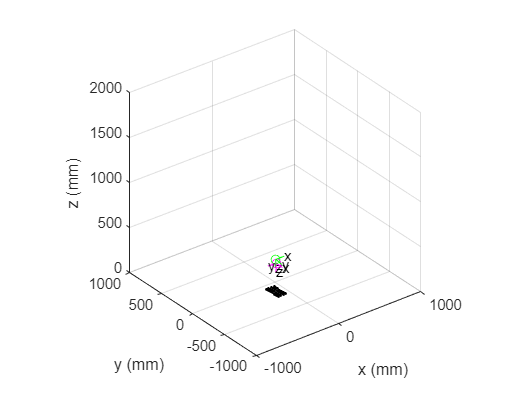

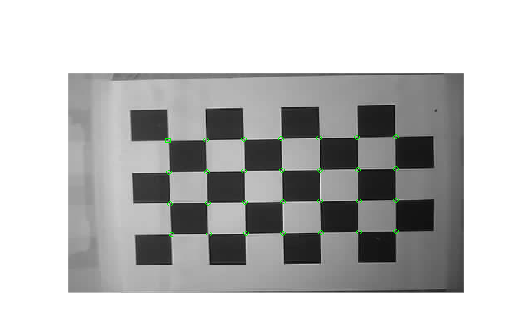

p3pResultFile = '.\Results\p3pResult.mat'

%RUN AND PLOT P3P FOR EACH CHECKERBOARD IMAGE
if importImages == true

    goodFrameCounter = 0;
    totalFrames = size(imageStream.time,2);
    imageSize = imageStream.res;

    for i=1:totalFrames
        disp(strcat("Working on frame ", string(i)));
        
        %Get current frame
        I=imageStream.img(:,:,i);
    
        %Find checkerboard corners
        [x_pnts_i, checkerSize_detected] = detectCheckerboardPoints(I);
        x_pnts_i = transpose(x_pnts_i);    
    
        %discard any frames where too few corners have been detected
        if (checkerSize_detected(1) ~= checkerSize(1)) || (checkerSize_detected(2) ~= checkerSize(2))
            disp(strcat("Discarding frame ", string(i)));
            continue
        end
        %Otherwise, continue:
        goodFrameCounter = goodFrameCounter +1;
        % 
        % if goodFrameCounter == 1
        %     startIndex = 1;
        % end
        
        %Run P3P
        p3pResult = runP3P(p3pResult, imageStream.time(i), x_pnts_i, X_pnts_W, K, Rt_rc2rq, imageSize, checkerSize, inlierThreshold, rtRounding,  'KneipN');
        plotStruct.traj = updatePlot(plotStruct.traj, p3pResult);
        
        % %Calculate error
        % if importSimLogs == true
        %     [~,closestIndex] = min(abs(cam_timeHist_GT-time_I));
        %     Rt_log_i = quad_rtHist_GT(:,:,closestIndex);
        %     p3pResult = calcRtError(p3pResult, quad_rtHist_GT, quad_timeHist_GT);    
        % end
    
        %Display checkerboard image for this iteration - for troubleshooting
        if (checkerSize_detected(1) <= checkerSize(1)) || (checkerSize_detected(2) <= checkerSize(1)) 
            if i==1
                checkerFig = figure();
                checkerAx = axes('Parent', checkerFig);
                checkerImg = imshow(imgFuncs.markDetectedCheckers(I, x_pnts_i), 'Parent', checkerAx);
            else
                checkerImg.CData = (imgFuncs.markDetectedCheckers(I, x_pnts_i));
                drawnow;
            end 
        end
    
     end
     
     p3pResultFile = fullfile('.', '/Results/p3pResult.mat')
     save(p3pResultFile,  'p3pResult'); 

     %Calculate errors?
    if (importMocap ==true) || (importSimLogs == true)
        for i=1:size(p3pResult.KneipN.time, 2)
            %Find the closest ground truth measurement for this time
            [closestDiff, closestIndex] = min(abs(groundTruth.quadTime(1,:)-p3pResult.KneipN.time(1, i)));
            for n=1:size(p3pResult.KneipN.quadPoseArr,2)
                [p3pResult.KneipN.quadPoseError(1, n, i), p3pResult.KneipN.quadPoseError(2, n, i)] = getPoseError(groundTruth.quadState(:,i), p3pResult.KneipN.quadPoseArr(:,n,i));
            end
        end
    end
end

## run 3D state estimator

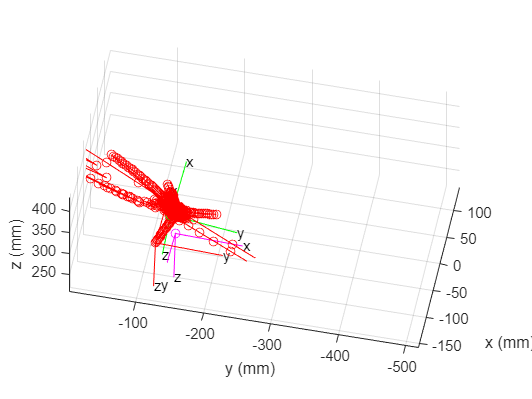

g = [0; 0; -9.79];
startCalc = 2; %Which log values to start at
endCalc =size(imu.time,2);

% %import sim log (again)
% if importSimLogs == true
%     [quad_rtHist_GT, quad_timeHist_GT, quad_stateHist_GT, cam_timeHist_GT, imuHist, imuHist_t] = imgFuncs.importSimLog(logFile);
%     %temp:
%     simData = load(logFile);
%     for i=1:size(simData.out.qdot_rq2rw.signals.values, 3)
%         qdotHist(:, i) = simData.out.qdot_rq2rw.signals.values(:, 1, i);
%     end
% 
%     %Get ground truth state history for comparison
%     x_hist_GT = quad_stateHist_GT(:,:);
%     x_k = [x_hist_GT(:,startCalc)]; %initialise from known point
% end


%set offsets
%Known coordinate transformations (mapping)
Rt_uw2rw = map.worldObjectStruct.transforms.rt_sim2world;
Rt_imu2rq = map.worldObjectStruct.transforms.rt_imu2genquad;
Rt_rc2rq = map.worldObjectStruct.transforms.rt_gencam2genquad;


%Import data
if importImages == true
    p3pResultFile = fullfile('.','/Results/p3pResult.mat');
    p3pResultLoad = load(p3pResultFile);
    p3pData = p3pResultLoad.p3pResult.KneipN;
end
    
%p3pTimes = datetime(p3pData.time, 'Format', 'yyyyMMdd_HHmmss_SSS');

%% IMPORT HISTORIES


%Get control input history
%u_hist = [imuHist(:,:); qdotHist]; %includes measurement times in row 1
u_hist = imu.calibdata;
%u_hist = imu.rawdata;
u_timeHist = imu.time;

%Get measurement history
if importImages == true
    % pos = p3pData.Rt(1:3, 4, :); %in m
    % rot = p3pData.Rt(1:3, 1:3, :);
    % pos = reshape(pos, 3, size(pos, 3));
    % ori_euler = zeros(3, size(rot, 3));
    % ori_quat = zeros(4, size(rot, 3));
    % for i=1:size(rot,3)
    %     eul = rotm2eul(rot(:,:,i), 'XYZ');
    %     ori_euler(:,i) = transpose(eul);
    %     ori_quat(:,i) = transpose(rotm2quat(rot(:,:,i)));
    % end
    z_timeHist = datetime(p3pData.time, 'Format', 'yyyyMMdd_HHmmss_SSS');
    % z_hist = [pos; ori_quat];
end

%% INITIALISE STATE AND ESTIMATOR VARIABLES

%Why using second value? There's something wrong with the first. probably due to derivatives in model)

%**** 10 elements ************
% %Initialise state - 10 el
% x_k = [groundTruth.quadState(1:10,startCalc)]; %maybe use existing knowledge
% %x_k = [0; 0; 0.32; 0; 1; 0; 0; 0;  0; 0]; %otherwise, initial guess
% 
% 
% %State covariance
% P_k = diag([0.01, 0.01, 0.01, 0.01, 0.01,  0.01, 0.01, 0.01, 0.01, 0.01]); %Initial, 10 el
% 
% %process noise covariance (noise space)
% Q = diag([0.01, 0.01, 0.01, 0.1, 0.1, 0.1]); %10 el - [w_g, w_acc]
% 
% %and measurement covariance
% W =diag([0.1, 0.1, 0.1, 0.1, 0.1, 0.1, 0.1]); %10 el 

%***************************


%**** 16 elements *****

%Initialise state - 16 el
ba_calib = [0;-0;-0];
bg_calib = [0.0; 0.0; 0.0];
%x_k = [x_hist_GT(:,start); ba_calib; bg_calib];

if importSimLogs ==true
    x_k = [groundTruth.quadState(:,syncedTime_zeroIndex_gt)]; %consider initialising from known position
elseif importMocap == true
    x_k = [groundTruth.quadState(:,syncedTime_zeroIndex_gt); 0;  0; 0; ba_calib; bg_calib];
else
    x_k = [0; 0; 0.32; 0; 1; 0; 0; 0;  0; 0; ba_calib; bg_calib]; %otherwise, initial guess
end

%State covariance
P_k = diag([0.001, 0.001, 0.001, ...
            0.001, 0.001, 0.001, 0.001, ...
            0.001, 0.001, 0.001, ...
            0.2, 0.2, 0.2, ...
            0.01, 0.01, 0.01]); %Initial, 16 el

%process noise covariance (noise space)
Q = diag([0.01, 0.01, 0.01, 0.1, 0.1, 0.1, 0.01, 0.01, 0.01, 0.001, 0.001, 0.001]); %16 el - [w_g, w_acc, w_ba, w_ba]

%and measurement covariance
W =diag([0.2, 0.2, 0.2, 0.1, 0.1, 0.1, 0.1]);  

%***************************

%At each time step
%Which time steps?
t_delta_dur = ((u_timeHist(1,2) - u_timeHist(1,1)));
t_delta = milliseconds(t_delta_dur) * 0.001;

%initialise EKF output history (do it after first state to get sizes right)
ekfResult = struct();
ekfResult.time = createArray(1, endCalc, 'datetime');
ekfResult.time = datetime(ekfResult.time, 'Format', 'yyyyMMdd_HHmmss_SSS');
ekfResult.stateEst = createArray(size(x_k, 1), endCalc, 'double');
ekfResult.P = createArray(size(x_k, 1), size(x_k, 1), endCalc, 'double');
ekfResult.processTerm = createArray(size(x_k, 1), endCalc, 'double');
ekfResult.measPred = createArray(7, endCalc, 'double');
ekfResult.statePred = createArray(size(ekfResult.stateEst), 'double');
ekfResult.z = createArray(7, endCalc, 'double');
ekfResult.input = createArray(6, endCalc, 'double');
ekfResult.error = createArray(2, endCalc, 'double'); %position, angle
ekfResult.Rt = zeros(3, 4, endCalc); %for plotting
ekfResult.zError = createArray(2, endCalc, 'double'); %position, angle
ekfResult.zHist = createArray(8, 0, 'double'); %include elapsed time in first position
ekfResult.elapsedTime = createArray(1,endCalc, 'double');

%Set first values
ekfResult.stateEst(:,1) = x_k;
ekfResult.time(:,1) = datetime(imu.time(1,startCalc), 'Format', 'yyyyMMdd_HHmmss_SSS');
ekfResult.elapsedTime(1,1) = 0;
ekfResult.P(:,:,1) = P_k;
ekfResult.processTerm(:,1) = zeros(size(x_k));
ekfResult.measPred(:,1) = zeros(7,1);
ekfResult.statePred(:,1) = zeros(size(x_k));
ekfResult.z(:,1) = NaN(7,1);
ekfResult.input(:,1) = zeros(6,1);


% rtHist_ekf(1:3, 1:3, 1) = quat2rotm(x_k(4:7)');
% rtHist_ekf(1:3, 4, 1) = x_k(1:3);

oldIndex = 0;
count = 1;
startTime_imu = ekfResult.time(1,1);
for i=startCalc:endCalc%size(u_hist,2)
   
    t_k = datetime(u_timeHist(1,i), 'Format', 'yyyyMMdd_HHmmss_SSS'); %current time
    u_k = u_hist(:, i); %current control input - INCLUDE SCALE FACTOR HERE?
    
    %check if there is a measurement for this time
    if importImages == true
        
        [closestDiff, closestIndex] = min(abs(z_timeHist(1,:)-t_k)); %find index of closest time
        if (((milliseconds(closestDiff)/1000) <= (t_delta)) && (z_timeHist(1, closestIndex) <= t_k) && closestIndex>oldIndex)%if it is close enough, and not ahead
            oldIndex = closestIndex;
            %Choose soln closest to previous estimate
            p3pSolns = reshape(p3pResult.KneipN.quadPoseArr(:,:,closestIndex), 7,[]);
            [p3pSoln,a,b] = chooseMinPoseErr(p3pSolns, x_k, 1.2, 2);
            %z_k = p3pResult.KneipN.poseArr(:,b,closestxIndex);
            z_k = p3pSoln;

            %Or choose min reproj
            % temp=p3pFuncs.transformPose(p3pResult.KneipN.mostInliers.Rt(:,:,closestIndex), p3pFuncs.invertRt(Rt_rc2rq));
            % z_k = [temp(1:3, 4); rotm2quat(temp(1:3, 1:3))'];
        else
            z_k = NaN; %no new measurement
        end
    else
        z_k = NaN; %no new measurement
    end
        %z_k = NaN;

    %run EKF to find next state
    [x_k, P_k, proTerm_k, xHat_k, zHat_k, z_k] = EKF_3dQuad_16el_funcs.EKF_loop(g, x_k, P_k, u_k, Q, z_k, W, t_delta, Rt_imu2rq, Rt_rc2rq, count);
    
   
    ekfResult.time(:,count+1) = (t_k+seconds(t_delta));
    ekfResult.stateEst(:,count+1) = x_k;
    ekfResult.processTerm(:,count+1) = proTerm_k;
    ekfResult.statePred(:,count+1) = xHat_k;
    ekfResult.measPred(:,count+1) = zHat_k;
    ekfResult.P(:,:,count+1) = P_k;
    ekfResult.input(:,count+1) = u_k;
    ekfResult.rt(:,:,count+1)= [quat2rotm(transpose(x_k(4:7, 1))), (x_k(1:3,1))];     %RECREATE RT matrix for plotting
    ekfResult.elapsedTime(1,count+1) = milliseconds(t_k - startTime_imu)/1000;
    %rtHist_ekf(:,1:3,i+1)= (quat2rotm(transpose(x_k(4:7, 1))));

    % Record z_hist
    if ~isnan(z_k)
       ekfResult.z(:,count+1) = z_k;
       ekfResult.zHist(:, end+1) = [ekfResult.elapsedTime(1,count+1); z_k];
    else
       ekfResult.z(:,count+1) = NaN(7,1);
    end
    
    count = count + 1;
end

plotStruct.traj.plotLines.EKF.Data = ekfResult.rt(:,:,1:2);
p3pPlotting.updateTraj(plotStruct.traj.plotLines.EKF.line, plotStruct.traj.plotLines.EKF.frameText, plotStruct.traj.plotLines.EKF.frameLines, ekfResult.rt(:,:,startCalc:endCalc))

drawnow

## Calculate errors

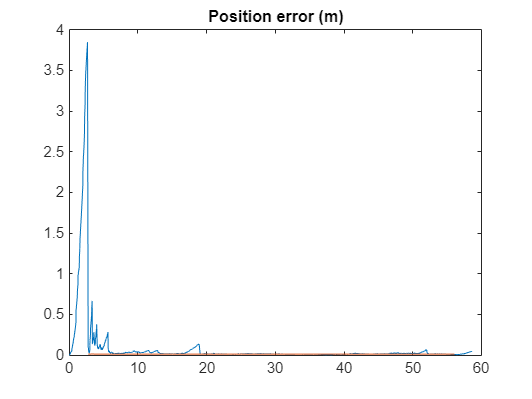

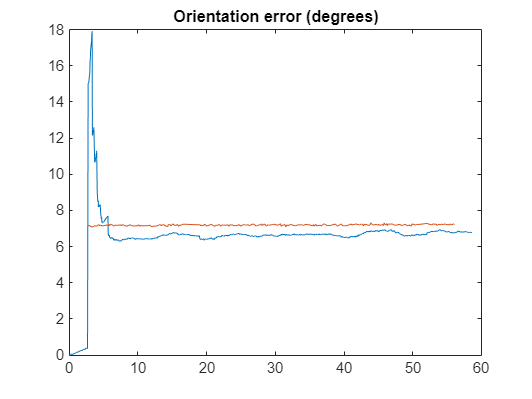

%Calculate EKF error
if importSimLogs == true || importMocap == true

    for i=1:size(ekfResult.stateEst, 2)
        %Find the closest ground truth measurement for this time
        [closestDiff, closestIndex] = min(abs(groundTruth.quadTime(1,:)-ekfResult.time(1, i)));
        %calculate the pose error
        [ekfResult.error(1, i),ekfResult.error(2, i)] = getPoseError(groundTruth.quadState(:, closestIndex), ekfResult.stateEst(:, i));
    end
    
    %Calculate P3P error
    ekfP3pErrArr = createArray(3,0, 'double');
    for i=1:size(ekfResult.z, 2)
        if ~isnan(ekfResult.z(1, i))
            %Find the closest ground truth measurement for this time
            [closestDiff, closestIndex] = min(abs(groundTruth.quadTime(1,:)-ekfResult.time(1,i)));
            % state_GT = quad_stateHist_GT(:, closestIndex);
            % state_P3P = [z_hist(2:4, i);
            %              quatmultiply(z_hist(5:8,i)', rotm2quat(R_rc2rq'))']; 
            % errArr_P3P(1, i) = z_hist(1, i);
            [ekfResult.zError(1, i), ekfResult.zError(2, i)] = getPoseError(groundTruth.quadState(:,closestIndex), ekfResult.z(:,i));
            ekfP3pErrArr(:,end+1) = [ekfResult.elapsedTime(1,i); ekfResult.zError(1, i); ekfResult.zError(2, i)];
        else
            ekfResult.zError(1:2, i) = NaN(2,1);
        end
    end
    
    %%Plot them
    %Position error
    errPlot_pos = figure();
    errAx_pos = axes('Parent', errPlot_pos);
    plot(errAx_pos, ekfResult.elapsedTime(1,:), ekfResult.error(1,:));
    hold on;
    plot(errAx_pos, ekfP3pErrArr(1,:), ekfP3pErrArr(2,:));
    title('Position error (m)');
    hold off;
    
    %Angular error
    errPlot_ang = figure();
    errAx_ang = axes('Parent', errPlot_ang);
    % Plot EKF error
    plot(errAx_ang, ekfResult.elapsedTime(1,:), ekfResult.error(2,:));
    hold on
    % Plot P3P error
    plot(errAx_ang, ekfP3pErrArr(1,:), ekfP3pErrArr(3,:));
    title('Orientation error (degrees)');
    hold off;
end 

## Plot state development

## Convert quaternions to euler angles --> more meaningful

%EKF estimates
numLoops = size(ekfResult.time, 2);
orientCov_eul = zeros(3,3,numLoops);
orient_EKF_eul = zeros(3,numLoops);
for t=1:numLoops

    %convert quaternion estimate to euler
    orient_EKF_eul(:,t) = rad2deg(quat2eul(ekfResult.stateEst(4:7, t)', 'XYZ'))'; %convert quaternion to euler
    q = ekfResult.stateEst(4:7, t);

    %propagate covariance
    orientCov_quat = ekfResult.P(4:7, 4:7, t);
    jacob = jacobianEultoQuat(q);
    orientCov_eul(:,:,t) = rad2deg(jacob * orientCov_quat * jacob');

end

%P3P estimates
if importImages ==true
    numP3P = size(ekfResult.zHist,2);
    orient_P3P_eul = zeros(3,numP3P);
    for t=1:numP3P
        %convert quaternion estimate to euler
        orient_P3P_eul(:,t) = rad2deg(quat2eul(ekfResult.zHist(5:8, t)', 'XYZ'))'; %convert quaternion to euler
    end
end

%Ground truth
if importMocap ==true || importSimLogs == true
    numGT = size(groundTruth.quadTime, 2);
    orient_gt_eul = zeros(3,numGT);
    for t=1:numGT
        %convert quaternion estimate to euler
        orient_gt_eul(:,t) = rad2deg(quat2eul(groundTruth.quadState(4:7, t)', 'XYZ'))'; %convert quaternion to euler
    end
end

%Recreate state histories
stateHist_EKF_eul = [ekfResult.stateEst(1:3, :); orient_EKF_eul; ekfResult.stateEst(8:end, :)];
stateHist_P3P_eul = [ekfResult.zHist(1:3, :); orient_P3P_eul];
stateHist_gt_eul = [groundTruth.quadState(1:3,:); orient_gt_eul; groundTruth.quadState(8:end,:)];


function j = jacobianEultoQuat(q)

j_11 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_12 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_13 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_14 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_21 = 2*q(4) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_22 = 2*q(3) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_23 = 2*q(2) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_24 = 2*q(1) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
j_31 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_32 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_33 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
j_34 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );

j = [j_11 j_12 j_13 j_14;
     j_21 j_22 j_23 j_24;
     j_31 j_32 j_33 j_34];
end


## DO PLOTTING:

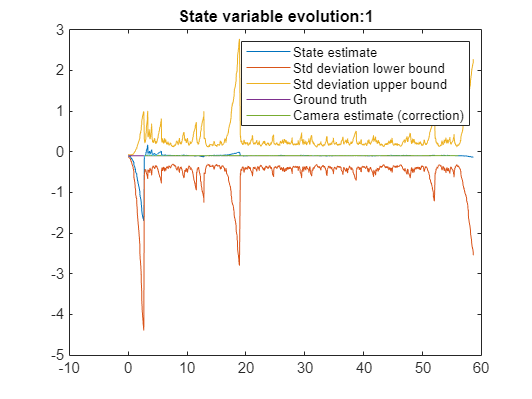

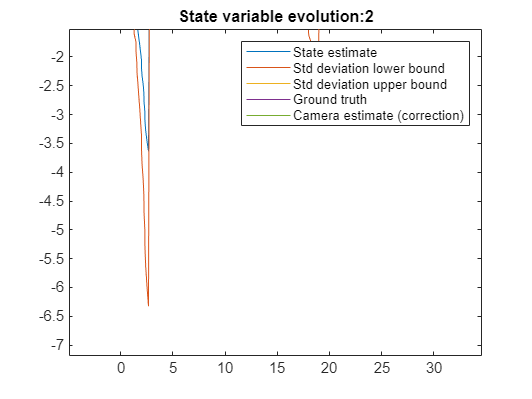

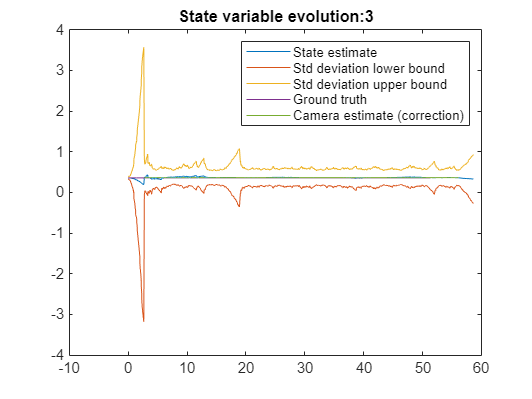

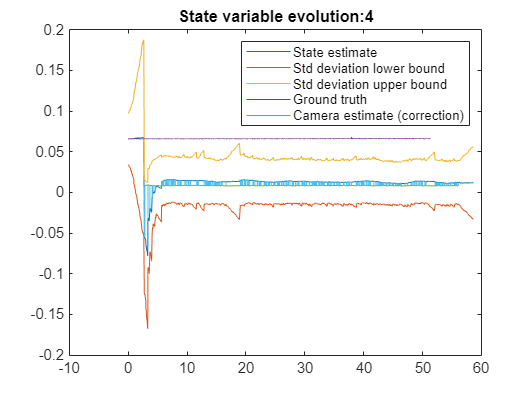

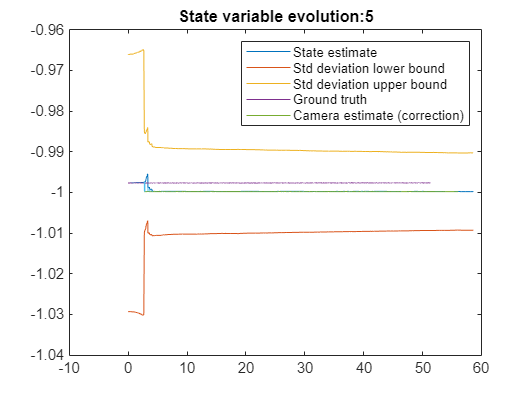

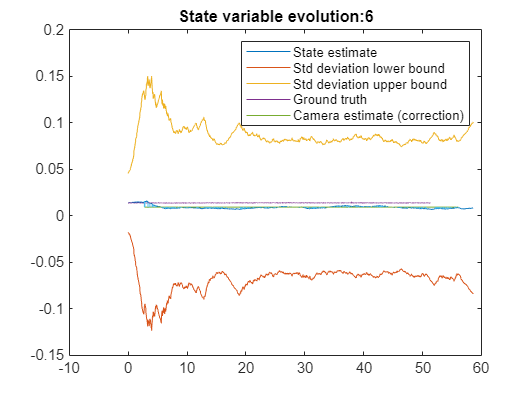

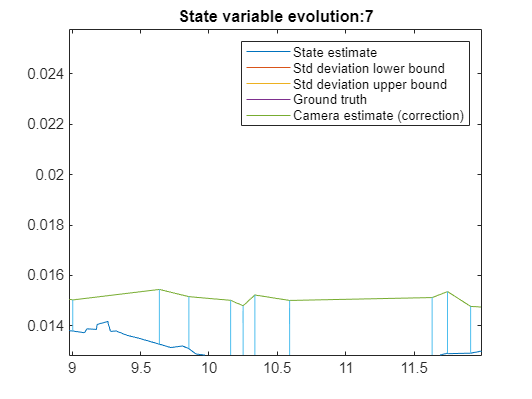

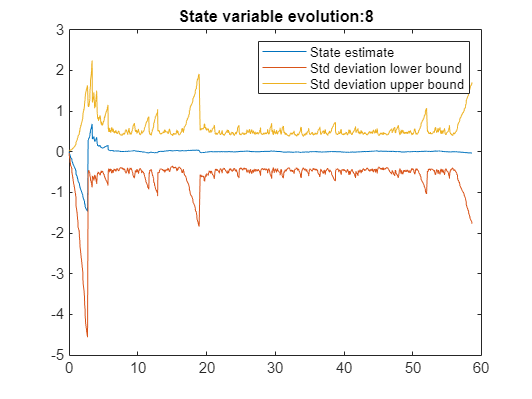

% match quternion direction in logs to estimate
if importSimLogs == true || importMocap == true
    for t=1:size(groundTruth.quadTime, 2)
        %find nearest state estimate
        [closestDiff, closestIndex] = min(abs(ekfResult.time(1,:)-groundTruth.quadTime(1,t)));
        q_comp = ekfResult.stateEst(4:7, closestIndex);
        q_gt = groundTruth.quadState(4:7, t);
        %Enforce quaternion constraints - closest quaternions
        if dot(q_comp, q_gt) < 0
            q_gt = -q_gt;
        end
        groundTruth.quadState(4:7, t) = q_gt;
    end
end

%Make plot for each state variable
numLoops = size(ekfResult.time, 2);
for i=1:size(x_k, 1)
    figure(); %create figure

    %PLOT CHANGING STATE
    x = ekfResult.elapsedTime(1,:);
    y = ekfResult.stateEst(i,:);
    plot(x, y);  
    hold on;
    
    %PLOT VARIANCE
    stateVariance = zeros(1, numLoops); %initialise array
    for t=1:numLoops
        stateVariance(1,t)=ekfResult.P(i,i,t);
    end
    stateVariance = sqrt(stateVariance);
    lowerCurve = y - abs(stateVariance);
    upperCurve = y + abs(stateVariance);
    plot(x, lowerCurve);
    hold on;
    plot(x, upperCurve);
    hold on;
    % fill(x, [y; upperCurve],[.9 .9 .9],'linestyle','none');
    % hold on;
    % 
    % fill(x, [lowerCurve; y],[.9 .9 .9],'linestyle','none');
    % hold on;
    %line(x,y)
    %errorbar(x, y, -dy, dy);
    % 
    % drawnow;
    % hold on;


    %%PLOT GROUND TRUTH
    if i <= 7
        if importSimLogs ==true || importMocap ==true
            %figure()
            x = groundTruth.elapsedTime_synced(1,syncedTime_zeroIndex_gt:end);
            y = groundTruth.quadState((i),syncedTime_zeroIndex_gt:end);
            plot(x, y);
            hold on;
        end
    end

    %plot corrections, if any (i.e., measurements in state space)
    if i<=7

        x = ekfResult.zHist(1,:);
        y = ekfResult.zHist(1+i,:);
        % scatter(x,y,5, "filled");
        % hold on;
        plot(x,y);
        hold on;

        %mark estimate that was corrected
        correctedEst = zeros(1, size(ekfResult.zHist, 2));
        for t=1:size(ekfResult.zHist, 2)
            t_k =  ekfResult.zHist(1, t);
            [closestDiff, closestIndex] = min(abs(ekfResult.elapsedTime(1,:)-ekfResult.zHist(1,t)));
            correctedEst(1, t) = ekfResult.stateEst(i, closestIndex);
        end
        y = correctedEst;
        %scatter(x, y, 10, "filled")
        %hold on;
        quiver(x, correctedEst, zeros(1, size(correctedEst, 2)), ((ekfResult.zHist(1+i,:)-correctedEst)), 0);
       
    end
    
    title(strcat('State variable evolution: ', string(i)));
    legend('State estimate', 'Std deviation lower bound', 'Std deviation upper bound', 'Ground truth', 'Camera estimate (correction)')

    hold off;


end

## Save results

saveFolder = parentFolder;

%% Save P3P result
save(strcat(saveFolder, '/p3pResult'), 'p3pResult');

%% Save EKF result


%% Save error plots


%% Save state variable evolution

% %for each state variable
% for i=1:size(stateHist_EKF_eul, 1)
% 
%     figure(); %create figure
%     title(strcat('State variable evolution: ', string(i)));
% 
%     %PLOT CHANGING STATE
%     x = stateHist_EKF(1,:);
%     y = stateHist_EKF_eul((1+i),:);
%     plot(x, y);
% 
%     drawnow;
%     hold on;
% 
%     %PLOT VARIANCE
%     %extract variance
%     stateVariance = zeros(1, size(stateHist_EKF, 2)); %initialise array
%     for t=1:size(stateHist_EKF, 2)
%         if ((i>=4) || (i<=6) %treat orientation separately
%             stateVariance(1,t) = orientCov_eul((i-3),(i-3),t);
%         else
%             stateVariance(1,t)=stateCovHist_EKF(i,i,t);
%         end
%     end
%     stateVariance = sqrt(stateVariance);
%     lowerCurve = y - abs(stateVariance);
%     upperCurve = y + abs(stateVariance);
%     plot(x, lowerCurve);
%     hold on;
%     plot(x, upperCurve);
%     hold on;
%     % fill(x, [y; upperCurve],[.9 .9 .9],'linestyle','none');
%     % hold on;
%     % 
%     % fill(x, [lowerCurve; y],[.9 .9 .9],'linestyle','none');
%     % hold on;
%     %line(x,y)
%     %errorbar(x, y, -dy, dy);
%     % 
%     % drawnow;
%     % hold on;
% 
% 
%     %PLOT GROUND TRUTH
% 
%     x = quad_timeHist_GT(1,:);
%     y = quad_stateHist_GT((i),:);
%     plot(x, y);
%     hold on;
% 
%     %plot corrections, if any (i.e., measurements in state space)
%     if i<=3
%         x = z_hist(1,:);
%         y = z_hist(1+i,:);
%         scatter(x,y,10, "filled");
%         hold on;
% 
%         %mark estimate that was corrected
%         correctedEst = zeros(1, size(z_hist, 2));
%         for t=1:size(z_hist, 2)
%             t_k =  z_hist(1, t);
%             [closestDiff, closestIndex] = min(abs(stateHist_EKF(1,:)-z_hist(1,t)));
%             correctedEst(1, t) = stateHist_EKF(1+i, closestIndex);
%         end
%         y = correctedEst;
%         %scatter(x, y, 10, "filled")
%         %hold on;
%         quiver(x, correctedEst, zeros(1, size(correctedEst, 2)), ((z_hist(1+i,:)-correctedEst)), 0);
% 
%     end
% 
%     legend('State estimate', 'Std deviation lower bound', 'Std deviation upper bound', 'True state', 'Camera estimate (correction)')
% 
%     hold off;
% 
% 
% end
% 
% function j = jacobianEultoQuat(q)
% 
% j_11 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_12 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_13 = (q(4)+q(1)) / ( (q(3)+q(2))^2 + (q(4)+q(1))^2 )  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_14 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_21 = 2*q(4) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
% j_22 = 2*q(3) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
% j_23 = 2*q(2) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
% j_24 = 2*q(1) / (( 1 - 4*( q(2)*q(3) + q(1)*q(4) )^2 )^(1/2));
% j_31 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_32 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_33 = (q(4) + q(1))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  -  (q(4)-q(1)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% j_34 = -(q(3) + q(2))/( (q(3)+q(2))^2 + (q(4)+q(1))^2)  +  (q(3)-q(2)) / ( (q(3)-q(2))^2 + (q(4)-q(1))^2 );
% 
% j = [j_11 j_12 j_13 j_14;
%      j_21 j_22 j_23 j_24;
%      j_31 j_32 j_33 j_34];
% end

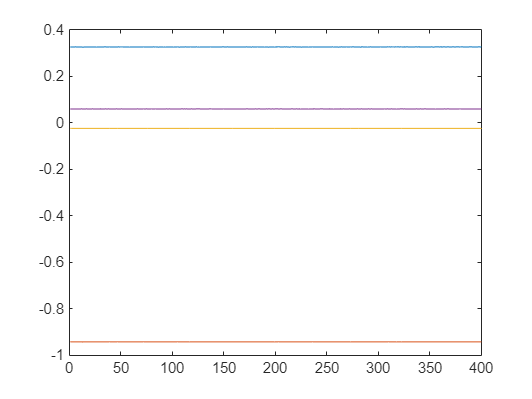

%plot p3p simply
p3p_q1 = reshape(p3pResult.KneipN.quadPoseArr(4:7,1,:), 4, []);
figure;
plot(p3p_q1');

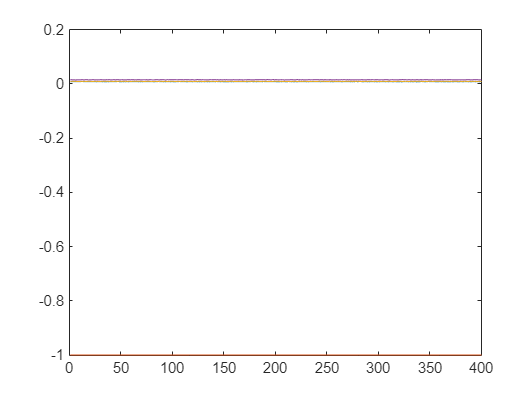


p3p_q2 = reshape(p3pResult.KneipN.quadPoseArr(4:7,2,:), 4, []);
figure;
plot(p3p_q2');

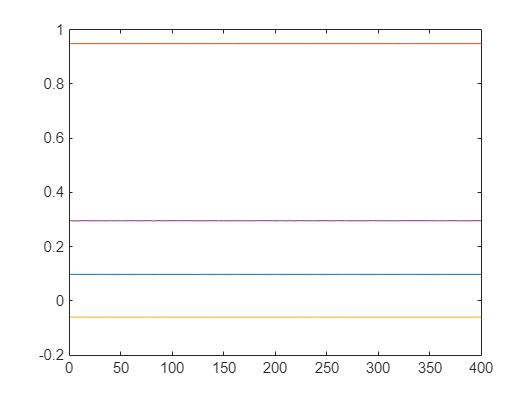


p3p_q3 = reshape(p3pResult.KneipN.quadPoseArr(4:7,3,:), 4, []);
figure;
plot(p3p_q3');

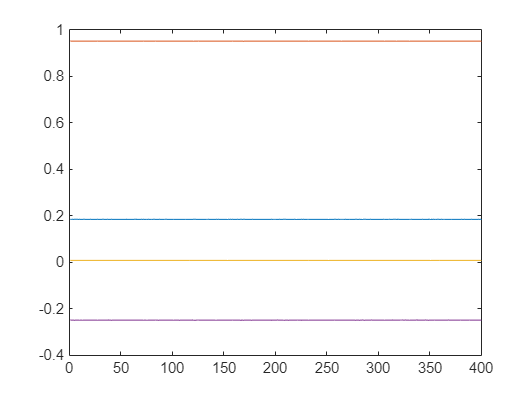


p3p_q4 = reshape(p3pResult.KneipN.quadPoseArr(4:7,4,:), 4, []);
figure;
plot(p3p_q4');

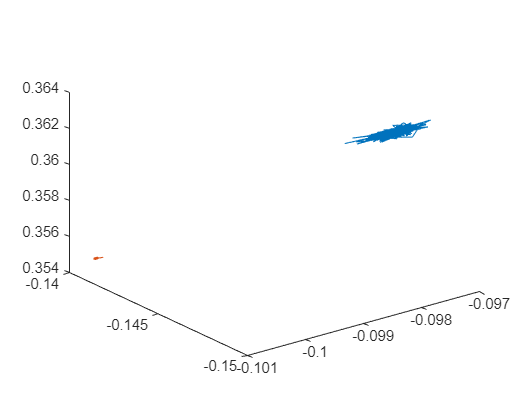


bestP3P_quadframe = findObjBestP3P(p3pResult.KneipN.quadPoseArr, p3pResult.KneipN.time, groundTruth.quadState, groundTruth.quadTime);
bestP3P_camframe = findObjBestP3P(p3pResult.KneipN.poseArr, p3pResult.KneipN.time, groundTruth.quadState, groundTruth.quadTime);
%bestP3P_quadframe = findObjBestP3P(p3pResult.KneipN.quadPoseArr, p3pResult.KneipN.time, quad_stateHist_GT, quad_timeHist_GT);

%bestP3P_quadframe = reshape(p3pResult.KneipN.quadPoseArr(:,1, :),7,[]);

for t=1:size(bestP3P_camframe, 2)
    R_c2w = quat2rotm((bestP3P_camframe(4:7, t))');
    t_c2w = bestP3P_camframe(1:3, t);
    T_c2w = [[R_c2w; 0 0 0] [t_c2w; 1]];
    T_q2c = [p3pFuncs.invertRt(Rt_rc2rq); 0 0 0 1];
    T_q2w = T_c2w * T_q2c;
    t_q2w = T_q2w(1:3, 4);
    q_q2w = rotm2quat(T_q2w(1:3, 1:3))';

    maybeBestP3P_camframe(:, t) = [t_q2w; q_q2w];
end

figure;
plot3(bestP3P_quadframe(1,:)', bestP3P_quadframe(2,:)', bestP3P_quadframe(3,:)');
hold on
% plot3(bestP3P_camframe(1,:)', bestP3P_camframe(2,:)', bestP3P_camframe(3,:)');
% hold on
% plot3(quad_pqHist_mocap(1,:)', quad_pqHist_mocap(2,:)', quad_pqHist_mocap(3,:)');
% hold on
plot3(groundTruth.quadState(1,:)', groundTruth.quadState(2,:)', groundTruth.quadState(3,:)');

% hold on
% plot3(maybeBestP3P_camframe(1,:)', maybeBestP3P_camframe(2,:)', maybeBestP3P_camframe(3,:)');
drawnow;
